# Numerical Methods in Physics

## Course Project - 2

#### BY: ABDULLAH BIN AAMIR

### Introduction

In this project i have simulated the motion of a Tippe Top. A Tippe Top is a science toy that looks like an ordinary top but has somewhat different shape and has the unique property of flipping on its tip after some revolutions.

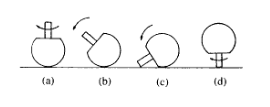

Figure 1.

The above picture shows what a tippe top looks like and its working as well. The top is carved out of a sphere. The sphere is cut at a plane and a handle is attached to this cut sphere as can be seen in the figure. When this new object is spinned along the handle, it spins with its axis of rotation passing through the handle but slowly this handle dips towards the surface. As the handle touches the surface, friction causes the top to tip on the handle and the rest of the body is lifted upwards. It is this tipping effect that makes it different from other tops and earns it the name 'Tippe Top'.

Note: the equations mentioned in this project have all been taken from the first reference and will not be derived here.

### Method and Explanation

Initially, there is a solid or a hollow sphere whose center of gravity coincides with its center of curvature. If we spin such a sphere, it will have no directional preference and will continuously change it's axis of rotation. However, when this sphere is cut along a plane as in the case of the tippe top, the center of gravity shifts downward due to unsymmetric mass distribution and no longer coincides with the center of curvature.  This leads to a preferred asis of rotation while spinning. This axis is the line that passes through the two centers. This axis then dips slowly as the top spins and carves out an angle $\theta$ from the vertical. This angle reaches 180 degrees and the top tips. A schematic is shown below.

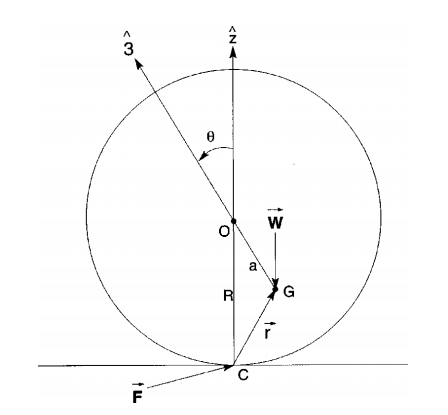

The above figure shows a spherical tippe top. Spherical tippe tops have similar mass distribution and work the same way as regular tippe tops except from the fact that they are easier to work with, for instance their moment of inertia is easier to calculate compared to that of the top shown in figure 1. The paper i based my analysis on uses the above shown schematic and gives the analysis based on a spherical tippe top. The analysis uses the regular (xyz) axes that are fixed to the surrounding and additional (123) axes  that are fixed at the top. The origin of xyz axes is point C where the top makes contact with the ground and the origin of 123 axes is the center of gravity, G. $\theta$ is the angle that 3 axis makes with the z axis. R is the radius of curvature and w is the weight of the top. F is the reaction force acting at the point of contact C in response to friction and the weight. 'a' is the distance between the center of gravity and the center of curvature.

It has been shown that there is a minimum amount of friction required by a tippe top to flip on its tip. My goal in this project is to find that minimum amount of friction for a tippe top with a specified mass M and radius of curvature R which has been spun with a specified set of initial conditions. The authors argue that the flip (transition from $\theta$ = 0 to $\pi$) occurs when there is slipping and slipping occurs when the following condition is satisfied. 

$F=F_{\textrm{fric}} =\frac{F_h }{F_z }$            (1)

In other words, when the reaction force at C equals the minimum friction force, the top flips. Hence if we find F at the time of flip, we can find the required friction force. In the above equation, $F_z$ is the reaction force to the weight by the surface given by:

$F_z \left(\theta \right)=1+a\left(\frac{1}{2}\sin \left(\theta \right)f^{\prime } \left(\theta \right)+\cos \left(\theta \right)f\left(\theta \right)\right)$            (2)

here:


$$f\left(\theta \right)={\dot{\theta} }^2 =\omega_1^2$$



$$f^{\prime } \left(\theta \right)=2\ddot{\theta} =2\frac{\mathrm{d}}{\mathrm{d}\theta }\omega_1$$


where $\omega_1$is the angular velocity with respect to 1 axis. In other words it is the rate of change of $\theta$. 


$$\omega_1 =\frac{d}{\mathrm{d}t}\theta$$


Now, 


$$F_h =\sqrt{F_x {\left(\theta \right)}^2 +F_y {\left(\theta \right)}^2 }$$


$F_x \left(\theta \right)=-\frac{I_3 K_R \sqrt{f\left(\theta \right)}}{f_3 {\left(\theta \right)}^3 }\left(\cos \left(\theta \right)-\frac{I_3 }{I_1 }\left(\cos \left(\theta \right)-a\right)\right)$                (3)

$F_y \left(\theta \right)=\frac{a\;\sin \left(\theta \right)F_z +\frac{1}{2}I_1 f^{\prime } \left(\theta \right)-I_1 \cot \left(\theta \right)\omega_2^2 +I_3 \omega_2 \omega_3 }{1-a\;\cos \left(\theta \right)}$            (4)

Here $K_R$is the Routh constant which will be defined later. $I_1$and $I_3$ are the moments of inetia along with the 1 and 3 axes respectively. $\omega_2$ and $\omega_3$ are angular velocities with respect to 2 and 3 axes respectively. $f_3 \left(\theta \right)\;\textrm{is}\;\textrm{given}\;\textrm{as}\;\textrm{follows}\ldotp$


$$f_3 \left(\theta \right)=\sqrt{\frac{1}{2}I_3 +\frac{1}{2}{\textrm{MR}}^2 {\;\sin }^2 \left(\theta \right)+\frac{1}{2}M\frac{I_3 }{I_1 }{\left(R\;\cos \left(\theta \right)-a\right)}^2 }$$


In the above equations to find the required friction for our top, we need to know how $\theta$,$\omega_1$, $\omega_2$ and $\omega_3$change with time. The authors of the paper have enlisted three contants namely, Energy Constant, Jellet Constant and Routh Constant that are set by the initial conditions and remain constant throughout the motion of the top. The expressions for the three constants are given as follows.

Energy Constant: 

$E=\frac{1}{2}\left\lbrack I_1 +M\left(R^2 +a^2 -2R\;a\;\cos \left(\theta \right)\right)\right\rbrack \omega_1^2 +\frac{1}{2}I_1 \omega_2^2 +\frac{1}{2}M{\left\lbrack \left(R\;\cos \left(\theta \right)-a\right)\omega_2 -R\;\sin \left(\theta \right)\omega_3 \right\rbrack }^2 +\frac{1}{2}I_3 \omega_3^2 +M\;g\;a\;\left(1-\cos \left(\theta \right)\right)$    (5)

Jellet Constant:

$K_J =I_1 \;R\;\sin \left(\theta \right)\omega_2 +I_3 \left(R\;\cos \left(\theta \right)-a\right)\omega_3$            (6)

  Routh Constant:

$K_R =\left\lbrack \frac{1}{2}I_3 +\frac{1}{2}M\;R^2 \;\sin^2 \left(\theta \right)+\frac{1}{2}M\;\frac{I_3 }{I_1 }{\left(R\;\cos \left(\theta \right)-a\right)}^2 \right\rbrack \omega_3^2$            (7)

Now thatwe have these constants, we have three equations for three unknown $\omega$'s since we want them all as a function of $\theta$. Once the initial conditions ($\theta \left(0\right),\dot{\theta} \left(0\right),\omega_2 \left(0\right),\omega_3 \left(0\right)$) have been specified, we can find the three constants. Once these constants have been set, we can use (7) to find $\omega_3$, which will allow us to find $\omega_2$using (6) and finally we can find $\omega_1$with the help of (5). Once we have the $\omega$'s we can use their values in (3) and (4) to find $F_h$which will eventually allow us to find the force of friction we need. 

### Code

clear all;close all

N_steps = 150000;
tau = 0.0001;

M = 0.0115; %kg
R = 0.016;  %m
g = 9.8;    %m/s^2
a = 0.07*R;
I1 = 0.399*M*R^2;   %kgm^2
I3 = 0.408*M*R^2;   %kgm^2

I have chosen the N_steps and  tau such that my time step is small enough and gives time interval of a few seconds which allows us to see how the top moves in the initial few seconds as this is where most of the action occurs. I have taken the above mentioned values directly from the paper to have consistent results.

%initializing arays
theta = zeros(1,N_steps);
omega1 = zeros(1,N_steps);
omega2 = zeros(1,N_steps);
omega3 = zeros(1,N_steps);
f_prime = zeros(1,N_steps);
time_array = linspace(1,N_steps*tau,N_steps);

%initiial conditions
theta(1)= 0.1;
omega1(1)= 0;   %rad/s
omega2(1)= 0;   %rad/s
omega3(1)= 155; %rad/s

Next I initialize the required arrays and the initial conditions. The values for the initial conditions were taken from the second reference as they were not available in the primary reference.


KR = (1/2*I3+1/2*M*R^2*(sin(theta(1)))^2+1/2*M*(I3/I1)*(R*cos(theta(1))-a)^2)*omega3(1)^2;
KJ = I1*R*sin(theta(1))*omega2(1)+I3*(R*cos(theta(1))-a)*omega3(1);
E = 1/2*(I1+M*(R^2+a^2-2*R*a*cos(theta(1))))*omega1(1)^2+1/2*I1*omega2(1)^2+1/2*M*((R*cos(theta(1))-a)*omega2(1)-R*sin(theta(1))*omega3(1))^2+1/2*I3*omega3(1)^2+M*g*a*(1-cos(theta(1)));


After getting the initial conditions, we can find the three constants mentioned earlier.

for i = 1:N_steps-1
    theta(i+1) = theta(i)+tau*omega1(i);
    omega3(i+1) = sqrt(KR/(1/2*I3+1/2*M*R^2*(sin(theta(i+1)))^2+1/2*M*(I3/I1)*(R*cos(theta(i+1))-a)^2));
    omega2(i+1) = (KJ-I3*(R*cos(theta(i+1))-a)*omega3(i+1))/(I1*R*sin(theta(i+1)));
    omega1(i+1) = sqrt((E-1/2*I1*omega2(i+1)^2-1/2*M*((R*cos(theta(i+1))-a)*omega2(i+1)-R*sin(theta(i+1))*omega3(i+1))^2-1/2*I3*omega3(i+1)^2-M*g*a*(1-cos(theta(i+1))))/(1/2*(I1+M*(R^2+a^2-2*R*a*cos(theta(i+1))))));
end

Once we have the three constants, we can now rearrange the equations (5),(6) and (7) to find the angular velocities. Here I use the Euler method to find $\theta$ iteratively. I move a small time step $\tau$ and find the next $\theta$, i then use this $\theta$ to find $\omega_3$, use that to find $\omega_2$ and use that to find the next $\omega_1$, which forms the input for finding the next $\theta$ and so on. This allows us to find the values of all the angular velocities and also tells us how $\theta$ changes throughout the motion of the tippe top.

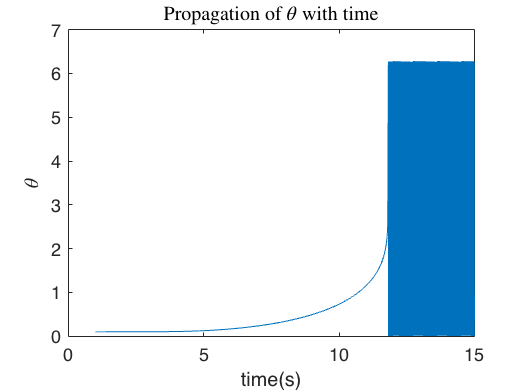

phi = wrapTo2Pi(real(theta));
k = 1;

while (theta(k) < 1*pi && k < N_steps)
    k = k+1;
end

figure(1);
plot(time_array, phi);
title('Propagation of ${\theta}$ with time','Interpreter','latex')
xlabel('time(s)');
ylabel('${\theta}$','Interpreter','latex');

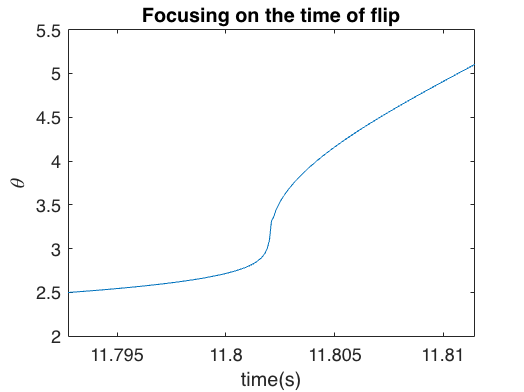

figure(2);
plot(time_array, phi);
title('Focusing on the time of flip')
xlim([time_array(k-100) time_array(k+100)]);
xlabel('time(s)');
ylabel('${\theta}$','Interpreter','latex');

Now that we have the detailed motion of the top and know how $\theta$ changes, we can search for the point when the $\theta$ becomes 180 degrees or $\pi$. The above code finds the index at which $\theta$ becomes $\pi$, we will use this index later to find the friction at that point in time as that is the friction that allows our top to flip. I wrap the angle so that it doesn't exceed 2$\pi$ as larger angles are just multiples of 2$\pi$ with some added angle, otherwise it shows angles approaching hundreds. However, we are not interested in what happens after the flip, we only need the point at which the flip occurs. The first plot shows the whole trajectory of $\theta$, while the second one shows the moment of the flip.

f = omega1.^2;
f3 = sqrt(1/2*I3+1/2*M*R^2*(sin(theta(1)))^2+1/2*M*(I3/I1)*(R*cos(theta(1))-a)^2);
step = theta(N_steps)-theta(N_steps-1);

for j = 1:N_steps-1
    f_prime(j) = 2*(omega1(j+1)-omega1(j))/step;
end

 Next I find the remiaining unknown terms in (2),(3) and (4) using the equations mentioned earlier.

Fz = 1+a.*(1/2.*sin(theta).*f_prime+cos(theta).*f);
Fy = (a.*sin(theta).*Fz+1/2.*I1.*f_prime-I1.*cot(theta).*omega2.^2+I3.*omega2.*omega3)./(1-a.*cos(theta));
Fx = (-I3*KR.*sqrt(f).*(cos(theta)-I3/I1.*(cos(theta)-a)))./(f3.^3);
Fh = sqrt(Fx.^2+Fy.^2);
F = Fh./Fz;

Now we have al the terms to find $F_x$, $F_y$and $F_z$, and we can finally calculate the required force of friction. The k'th index of our friction values array will give us the required friction.

fprintf('The flip occurs at: %1.2fs',time_array(k)); 

The flip occurs at: 11.80s

fprintf('The minimum required coefficient of friction for the flip is: %1.2f',abs(F(k))); 

The minimum required coefficient of friction for the flip is: 0.26

Lastly, we can print out the result.

### Conclusion

In this project I have found the minimum friction required for a specific tippe top to flip if it is spun in a certain way. The coefficient of friction obtained by using the initial conditions in the second reference gives us a co-efficient of friction of 0.26 which is a significantly rough surface. As Grey et al. mention in their paper, earlier research has shown that the tippe top takes significantly longer to flip in conditions of low friction. Wheras in our case, the top was able to flip in only 11.8 seconds which is quite reasonable and is close to what is observed in most standard tippe tops, since our surface was able to provide the required friction. 

### References

Prinmary reference:  C. G. Gray and B. G. Nickel, Constants of the motion for nonslipping tippe tops and other tops with round pegs, American Journal of Physics 68 (2000), no. 9, 821–828.

Secondary reference: Rutstam, N. (2013). Analysis of Dynamics of the Tippe Top (PhD dissertation). Linköping University Electronic Press, Linköping. Retrieved from http://urn.kb.se/resolve?urn=urn:nbn:se:liu:diva-88316

Figure 1 taken from: Or, A. (1994). The Dynamics of a Tippe Top. *SIAM Journal on Applied Mathematics,* *54*(3), 597-609. Retrieved November 6, 2020, from http://www.jstor.org/stable/2102374